Relações úteis:

𝑀𝑝 = 𝑒^(− 𝜁𝜋/1−𝜁^2)

𝑡𝑠(2%) = 4/𝜁𝜔𝑛

𝑡𝑟 = (𝜋 − 𝛽) / 𝜔𝑑

𝑡𝑝 = 𝜋/𝜔𝑑

𝜔𝑑 = 𝜔𝑛 sqrt( 1 − 𝜁^2)

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




Gs = 165/((s+1)*(s+2)*(s+10))

Gs =
 
            165
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.



Gsmf = feedback(Gs, 1)

Gsmf =
 
             165
  -------------------------
  s^3 + 13 s^2 + 32 s + 185
 
Continuous-time transfer function.



pole(Gs)

ans =   -10.0000
   -2.0000
   -1.0000


pole(Gsmf)

ans =  -11.6162 + 0.0000i
  -0.6919 + 3.9303i
  -0.6919 - 3.9303i


O polo dominante é o mais perto do eixo imaginario:

**Usaremos as formulas:**

 Y = 𝜔𝑛:

            Y = sqrt(raizReal^2+raizImaginaria^2 )

 X = ζ :

           X = raizReal/Y

raizReal = -0.6919

raizReal = -0.6919

raizImaginaria = 3.9303

raizImaginaria = 3.9303

Y = sqrt(raizReal^2+raizImaginaria^2 )

Y = 3.9907

X = raizReal/Y

X = -0.1734

calcuremos a constante de erro estatico (Kv) para o sistema:

    syms s declara s como uma variavel 

    precisa declara a função encontrada la em Gs

   ** --> se o sistema é do tipo 0 (posição) DEGRAU [zero polos na origem]:**

            usa: Fx = (F(p));  para achar o Kv

                       erro = 1/1+Kv

                       Kvc = (1/erro)-1

    **--> se o sistema é do tipo 1 (velocidade) RAMPA [um polos na origem]:**

            usa: Fx = p*(F(p));    para achar o Kv

                       erro = 1/Kv

                        Kvc = (1/erro)

     **--> se o sistema é do tipo 2 (aceleração) [dois polos na origem]:**

            usa: Fx = P^2*(F(p));    para achar o Kv

                        erro = 1/Kv

                         Kvc = (1/erro)

syms p;
Fx = p*(4/(p^2+0.5*p))

$$Fx = \frac{4\,p}{p^{2}+\frac{p}{2}}$$

Kv = limit(Fx, p, 0) %vpa retorna o decimal da resposta

$$Kv = 8$$

Kv1 = 8

Kv1 = 8

erro = 1/Kv1

erro = 0.1250

Se deseja obter um sobresinal (Mp) de 16,03% e um tempo de subida (Ts) de 1,6 segundos

[1] Usaremos as formulas: 

            Mp = e^( (X * PI) / ( sqrt(1 - (X^2) ) )   ---->  onde X é o amortecimento 

            Ts = 4 / X *  Y                             ----> onde X é o amortecimento e Y a frequencia natural

Isolando X:

            X = sqrt( (log(Mp)^2) / ( (pi^2) + (log(Mp)^2) )

            X = ζ

isolando Y:

            Y = 4/(Ts*X)

            Y = 𝜔𝑛

Mp = 0.05

Mp = 0.0500

X = sqrt(((log(Mp)^2)/((pi^2)+(log(Mp)^2))))

X = 0.6901

Ts = 2

Ts = 2

Y = 4/(Ts*X)

Y = 2.8981

Polos da função de transferencia 

poloReal = -(X*Y)

poloReal = -2

poloImaginario = Y* sqrt(1-X^2)

poloImaginario = 2.0974

[2] Verificar se os polos desejados fazem parte do lugar das raizes de Gs

    -> para isso o angulo deve ser um multiplo de + ou - 180 graus

    -> formula é dada por 4/s(s+2)        -> sendo 's' a relação dos dois angulos encontrados                                 

                        s = anguleAlvo

`Verificação da condição de ângulo:`

raizesJuntas= poloReal + poloImaginario*j

raizesJuntas = -2.0000 + 2.0974i

anguleAlvo = angle((evalfr(Gs, raizesJuntas)))*180/pi

anguleAlvo = 139.8181

** se o resultado do angulo não for multiplo de 180, deve se usar o compensador de avanço **

        Deve se calcular o angulo compensado:

                        anguloCompensado = 𝜙

                        anguloCompensado = -180 - ( -angleAlvo)

if anguleAlvo > 0
    anguloCompensado = (-180 - ( -anguleAlvo) )
else
    anguloCompensado = 180 -(-anguleAlvo)    
end

anguloCompensado = -40.1819

calculamos a distancia entre o polo da planta e o polo com angulo encontrado:

dist = poloImaginario / (tan(anguloCompensado*pi/180))

dist = -2.4835

XZero = (-poloReal - dist)

XZero = 4.4835

calculamos a constante de tempo derivativa

Td = 1/abs(XZero)

Td = 0.2230

calculo do granho proporcional do controlador:

Kp = abs(1/evalfr(Td*(s+XZero)*Gs, raizesJuntas))

Kp = 0.3369

O PI n pode alterar sgnificativamente o sistemda de forma que deve estar entre uma faixa de:

    -5° < angulo < 0°    e      ganho aproximadamente 1

por isso escolhemos um Ti que obedeça a regra acima:

Ti = 20

Ti = 20

possivelPI = ((s+1/Ti)/s)

possivelPI =
 
  s + 0.05
  --------
     s
 
Continuous-time transfer function.



possivelPIGanho = abs(evalfr(possivelPI, raizesJuntas))

possivelPIGanho = 0.9882

possivelPIAngulo = angle(evalfr(possivelPI, raizesJuntas))*180/pi

possivelPIAngulo = -0.7240

e assim o controlador se da por:

GControladorPID = Kp*Td*(s+XZero)*possivelPI

GControladorPID =
 
  0.07515 s^2 + 0.3407 s + 0.01685
  --------------------------------
                 s
 
Continuous-time transfer function.



e em malha fechada:

Gmf = (GControladorPID * Gs)/(1+(GControladorPID * Gs))

Gmf =
 
         12.4 s^6 + 217.4 s^5 + 1130 s^4 + 2083 s^3 + 1213 s^2 + 55.59 s
  ------------------------------------------------------------------------------
  s^8 + 26 s^7 + 245.4 s^6 + 1089 s^5 + 2674 s^4 + 3363 s^3 + 1613 s^2 + 55.59 s
 
Continuous-time transfer function.



Gmf = minreal(Gmf)

Gmf =
 
         12.4 s^2 + 56.21 s + 2.78
  ----------------------------------------
  s^4 + 13 s^3 + 44.4 s^2 + 76.21 s + 2.78
 
Continuous-time transfer function.



pole(Gmf)

ans =   -9.0058 + 0.0000i
  -1.9785 + 2.0896i
  -1.9785 - 2.0896i
  -0.0373 + 0.0000i


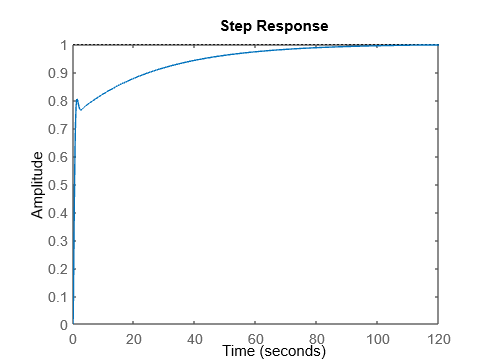

step(Gmf)

stepinfo(Gmf)

ans = struct with fields:
         RiseTime: 25.2772
    TransientTime: 68.6134
     SettlingTime: 68.6134
      SettlingMin: 0.9000
      SettlingMax: 0.9967
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9967
         PeakTime: 116.8855
